# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
for i = 2:length(SIDS)-2
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

sid = 0b5a2ePlayback

%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =    1.0e-25 *

    0.8924
         0


tbl =     'Source'           'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'             'Prob>F'    
    'anovaNumStims'    [4.7872e+04]    [   3]    [        0]    [1.5957e+04]    [   40.1442]    [8.9238e-26]
    'anovaBetaSID'     [8.6443e+06]    [   7]    [        0]    [1.2349e+06]    [3.1066e+03]    [         0]
    'Error'            [3.9070e+06]    [9829]    [        0]    [  397.5018]              []              []
    'Total'            [1.2951e+07]    [9839]    [        0]              []              []              []


stats =          source: 'anovan'
          resid: [9840x1 double]
         coeffs: [13x1 double]
            Rtr: [11x11 double]
       rowbasis: [11x13 double]
            dfe: 9829
            mse: 397.5018
    nullproject: [13x11 double]
          terms: [2x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [3x1 double]
     coeffnames: {13x1 cell}
           vars: [13x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


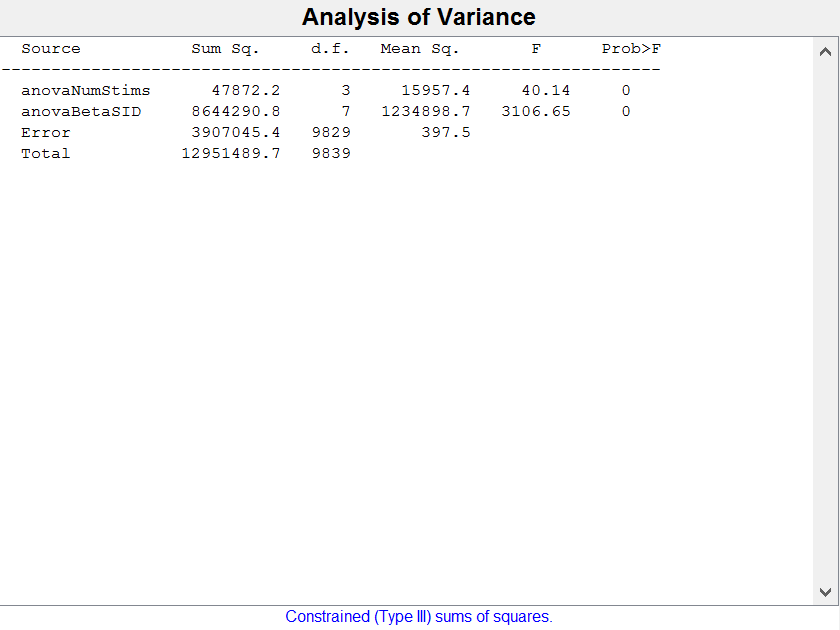

figure
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'})
% 
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})
% [p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})

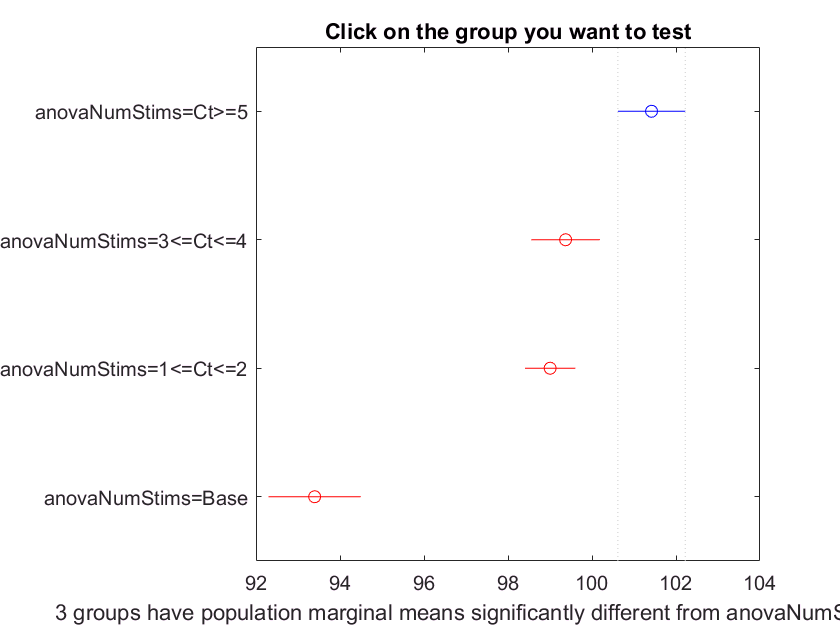

c =     1.0000    2.0000    0.4177    2.0466    3.6754    0.0068
    1.0000    3.0000    1.0156    2.4142    3.8127    0.0001
    1.0000    4.0000    6.1246    8.0217    9.9188    0.0000
    2.0000    3.0000   -1.0457    0.3676    1.7809    0.9091
    2.0000    4.0000    4.0635    5.9752    7.8868    0.0000
    3.0000    4.0000    3.9014    5.6075    7.3137    0.0000


m =   101.4177    0.4544
   99.3711    0.4613
   99.0035    0.3148
   93.3960    0.5939


h =   Figure (4: Multiple comparison of population marginal means) with properties:

      Number: 4
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'


% [p,tbl,stats] = anovan(anova2,{anovaNumStims,anovaBetaSID},'varnames',{'anovaNumStims','anovaBetaSID'})
% 

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [101.4177]    [0.4544]
    'anovaNumStims=3<=Ct<=4'    [ 99.3711]    [0.4613]
    'anovaNumStims=1<=Ct<=2'    [ 99.0035]    [0.3148]
    'anovaNumStims=Base'        [ 93.3960]    [0.5939]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [92 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [92 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [92 102]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1192 0.7750 0.8026]
            Units: 'normalized'

  Show all properties


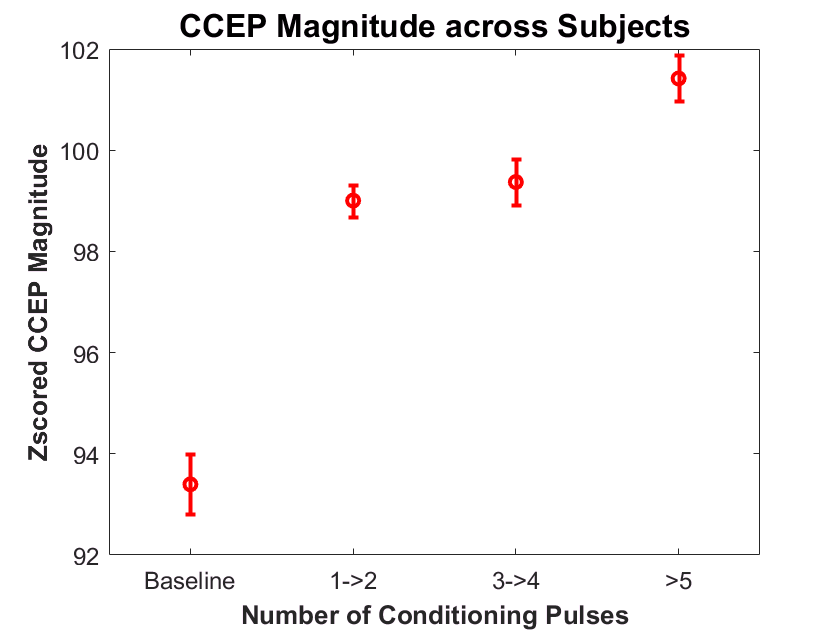

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

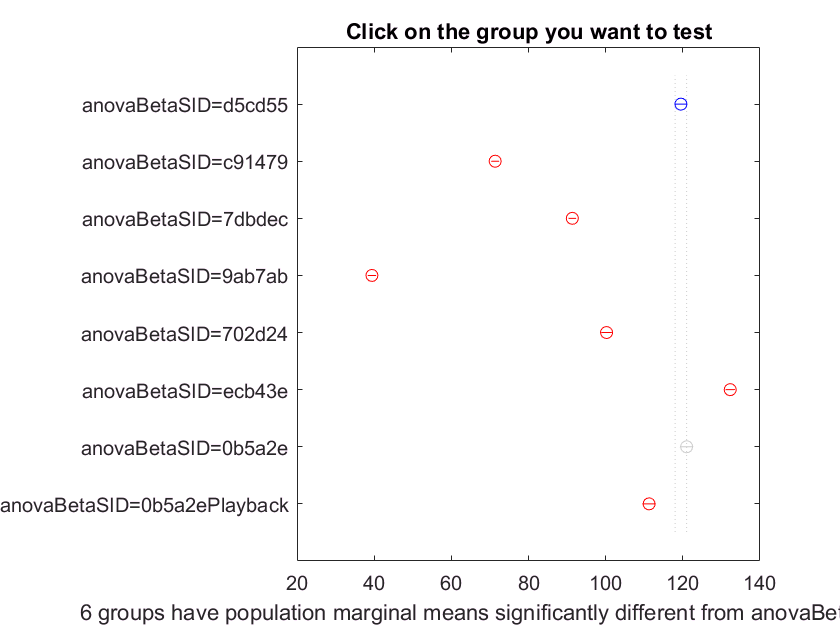

results1 =     1.0000    2.0000   45.6400   48.1366   50.6331    0.0000
    1.0000    3.0000   25.6327   28.1431   30.6534    0.0000
    1.0000    4.0000   77.4662   80.0779   82.6895    0.0000
    1.0000    5.0000   16.4006   19.2737   22.1468    0.0000
    1.0000    6.0000  -15.5278  -12.7777  -10.0277    0.0000
    1.0000    7.0000   -4.6681   -1.4789    1.7102    0.8551
    1.0000    8.0000    5.0576    8.2468   11.4360    0.0000
    2.0000    3.0000  -21.9623  -19.9935  -18.0246    0.0000
    2.0000    4.0000   29.8604   31.9413   34.0223    0.0000
    2.0000    5.0000  -31.2724  -28.8629  -26.4534    0.0000



figure
results1 = multcompare(stats,'Dimension',[2])

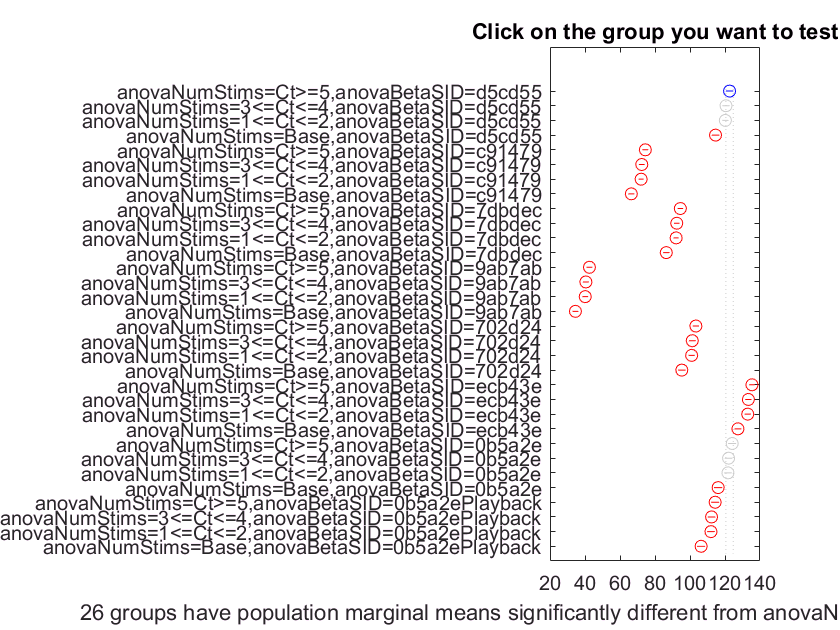

cM =     1.0000    2.0000   -0.3503    2.0466    4.4434    0.2527
    1.0000    3.0000    0.3563    2.4142    4.4721    0.0038
    1.0000    4.0000    5.2302    8.0217   10.8132    0.0000
    1.0000    5.0000   45.0228   48.1366   51.2503    0.0000
    1.0000    6.0000   46.2189   50.1831   54.1474    0.0000
    1.0000    7.0000   46.7228   50.5507   54.3786    0.0000
    1.0000    8.0000   51.9713   56.1583   60.3452    0.0000
    1.0000    9.0000   25.0121   28.1431   31.2740    0.0000
    1.0000   10.0000   26.1576   30.1896   34.2217    0.0000
    1.0000   11.0000   26.5778   30.5572   34.5366    0.0000


mM =   122.6204    0.8393
  120.5738    0.8183
  120.2062    0.6938
  114.5987    0.8974
   74.4838    0.6415
   72.4373    0.6293
   72.0697    0.4889
   66.4621    0.7180
   94.4773    0.5924
   92.4307    0.6048


hM =   Figure (7: Multiple comparison of population marginal means) with properties:

      Number: 7
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1.0003e+03 917.6667 560 420.0000]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaBetaSID=d5cd55'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=d5cd55'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=d5cd55'
    'anovaNumStims=Base,anovaBetaSID=d5cd55'
    'anovaNumStims=Ct>=5,anovaBetaSID=c91479'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=c91479'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=c91479'
    'anovaNumStims=Base,anovaBetaSID=c91479'
    'anovaNumStims=Ct>=5,anovaBetaSID=7dbdec'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=7dbdec'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=7dbdec'
    'anovaNumStims=Base,anovaBetaSID=7dbdec'
    'anovaNumStims=Ct>=5,anovaBetaSID=9ab7ab'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=9ab7ab'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=9ab7ab'
    'anovaNumStims=Base,anovaBetaSID=9ab7ab'
    'anovaNumStims=Ct>=5,anovaBetaSID=702d24'
    'anovaNumStims=3<=Ct<=4,anovaBetaSID=702d24'
    'anovaNumStims=1<=Ct<=2,anovaBetaSID=702d24'
    'anovaNumStims=Base,anovaBetaSID=702d24'
    'anovaNumStims=Ct>=5,anovaBetaSID=ecb43e'



% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

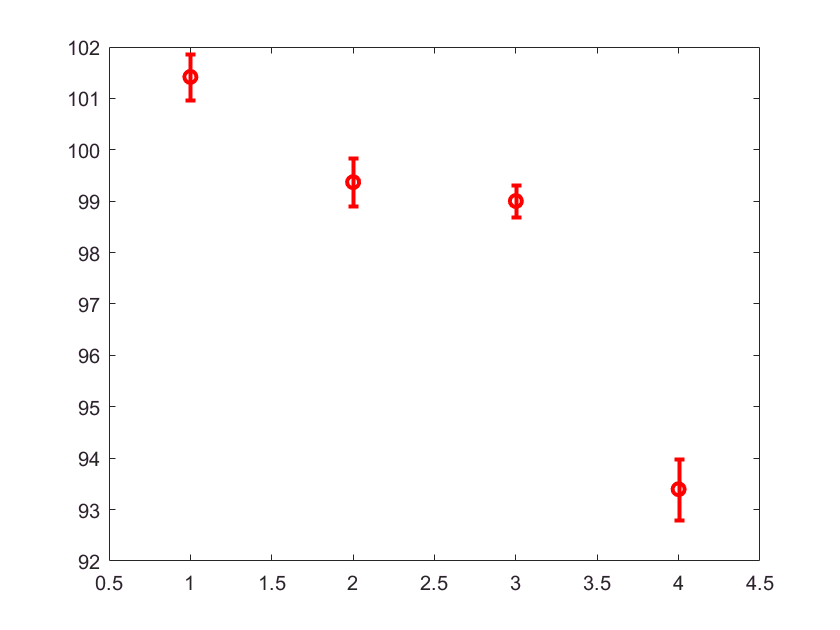

errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')